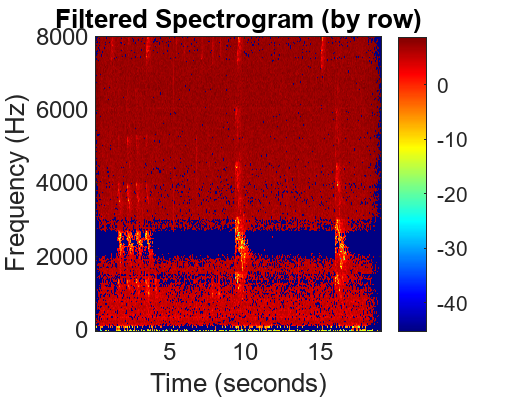

% Load the audio file
[audioData, fs] = audioread('hawk_337669.mp3');
soundsc(audioData,fs);


if size(audioData, 2) == 2
    audioData = mean(audioData, 2);
end

% Downsample to 16 kHz
targetFs = 16000;
if fs ~= targetFs
    audioData = resample(audioData, targetFs, fs);
    fs = targetFs;
end


% Define your window length & step size in terms of number of samples.
winlen = 512;
Step = 256;

% This function converts the x-vector into a matrix where each row is a
% single frame
xf = FrameSignal(audioData,winlen,Step);

nfft = winlen; 

n_frames = size(xf, 1);  
STFT = zeros(nfft, n_frames); 

window = hamming(winlen);

for i = 1:n_frames
    frame = xf(i, :)' .* window;  
    fft_frame = fft(frame, nfft); 
    STFT(:, i) = fft_frame;  
end

[STFT_ref,f,t] = spectrogram(audioData,window,Step,winlen,fs);



% Parameters for STFT
frameLength = 512;
overlapLength = 256;

% Apply STFT with a Hamming window
window = hamming(frameLength, 'periodic');
[S, F, T] = spectrogram(audioData, window, overlapLength, frameLength, fs);



% Normalize spectrogram for better CNN processing
S = abs(S); % Magnitude of the spectrogram
S = log(S + eps); % Log scale to compress dynamic range


% Low-pass filter with cutoff frequency 6250 Hz
lowPassFilter = designfilt('lowpassiir', 'FilterOrder', 8, ...
                           'HalfPowerFrequency', 6250, 'SampleRate', fs);

% Apply the low-pass filter to the spectrogram
S_filtered = filter(lowPassFilter, S); 


% Get the number of rows (frequencies) and columns (time bins)
[numRows, numCols] = size(S_filtered); 

% Define the filtering threshold
thresholdFactor = 1.5;

% Loop through each row (frequency band)
for row = 1:numRows
    % Calculate the mean and variance for the current row (across all time bins)
    row_mean = mean(S_filtered(row, :));
    row_variance = var(S_filtered(row, :));
    
    % Loop through each cell in the spectrogram (a 30x10 grid)
    for col = 1:numCols
        % Get the value of the cell
        cell_value = S_filtered(row, col);
        
        if cell_value < (thresholdFactor * (row_mean + row_variance))
            % Set the cell to zero if it doesn't meet the threshold
            S_filtered(row, col) = 0;
        end
    end
end


% Plot the original and filtered spectrograms
% figure;
% imagesc(T, F, 10*log10(abs(S_filtered)));
% set(gca, 'YDir', 'normal');
% xlabel('Time (seconds)');
% ylabel('Frequency (Hz)');
% title('Filtered Spectrogram (by row)');
% colorbar;
% colormap jet;